# F1 Model Simulator

## Vehicle Dynamics

%% f1_vehicle_params.m
% Script MAESTRO de inicializacion - correr solo este antes de simular.
%
% Carga los parametros del Vehiculo (estructura "veh") y ademas llama a
% los scripts de Circuito/Cronometraje, para que una sola corrida deje
% todo el workspace listo: veh, la curvatura/velocidad limite del
% circuito, y la geometria de la linea de meta.
%
% Orden de ejecucion (no cambiar el orden: los ultimos dos dependen del
% archivo silverstone_centerline.csv, no entre si):
%   1. Este script (parametros del vehiculo)
%   2. f1_track_curvature.m  (circuito: curvatura, velocidad limite)
%   3. f1_finish_line_params.m (cronometraje: geometria de la meta)

%% --- Masa y geometria (Vehicle Body 3DOF, variante Dual Track) ---

veh.m             = 770;    % [kg] masa minima 2026 (piloto incl., combustible excl.) - CONFIRMADO reglamento
veh.wheelbase     = 3.4;    % [m]  distancia entre ejes, maximo reglamentario 2026    - CONFIRMADO reglamento

veh.track_f       = 1.6;    % [m]  track delantero  - ESTIMADO (no publicado oficialmente)
veh.track_r       = 1.6;    % [m]  track trasero    - ESTIMADO (no publicado oficialmente)

veh.cg_height     = 0.275;  % [m]  altura del CG     - ESTIMADO (literatura vehicle dynamics: 0.25-0.30 m)
veh.weight_dist_r = 0.55;   % [-]  fraccion de masa sobre el eje trasero - ESTIMADO (~45/55 tipico en monoplazas)

% Distancias del CG a cada eje, derivadas del reparto de masa:
veh.a = veh.wheelbase * veh.weight_dist_r;        % [m] CG -> eje delantero
veh.b = veh.wheelbase * (1 - veh.weight_dist_r);  % [m] CG -> eje trasero

% Momento de inercia en yaw (Izz) - ESTIMADO con una regla practica de
% vehicle dynamics: (wheelbase / radio de giro en yaw)^2 ~ 7.5 para un
% F1 (vs. ~3 para un sedan/station wagon - los F1 son mas "puntuales",
% con la masa concentrada cerca del CG).
veh.k_yaw = veh.wheelbase / sqrt(7.5);   % [m] radio de giro en yaw
veh.Izz   = veh.m * veh.k_yaw^2;         % [kg*m^2] momento de inercia en yaw

%% --- Neumaticos (Combined Slip Wheel 2DOF, o Dugoff Wheel 2DOF para la version simple) ---

% TODO: coeficientes Magic Formula 6.2 / Dugoff.
% Punto de partida: usar los valores built-in que trae el bloque.
% Ajustar aqui cuando calibremos el modelo de neumatico con datos propios.

%% --- Tabla lateral del neumatico (Vehicle Body, "Mapped slip angle") ---
% f1_lateral_tire_table.m genera alpha_brk, Cy_f_tab y Cy_r_tab, que el
% Vehicle Body usa como: Cy_f_data = Cy_f_tab, Cy_r_data = Cy_r_tab,
% alpha_f_brk = alpha_r_brk = alpha_brk. Abre una figura de verificacion.
fprintf('\n--- Cargando tabla lateral del neumatico ---\n');


--- Cargando tabla lateral del neumatico ---


Delantero: Cy(0) = 160000 N/rad | pico mu_y = 1.70 en 9.7 grados
Trasero:   Cy(0) = 192000 N/rad | pico mu_y = 1.80 en 8.6 grados
Tabla: 161 puntos, alpha de -0.80 a 0.80 rad


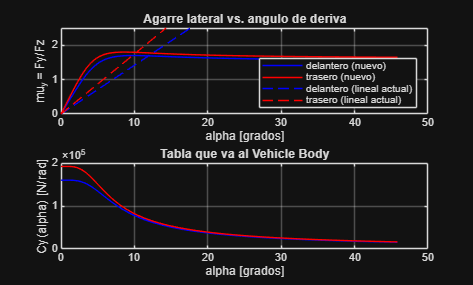

f1_lateral_tire_table


%% --- Powertrain (Mapped Motor + Open Differential) ---

% TODO: curva de par vs. rpm del Mapped Motor, limites de torque del
% Open Differential. Pendiente hasta que definamos el powertrain
% con mas detalle.

%% --- Resumen en consola (util para verificar rapido tras cada edicion) ---

fprintf('--- Parametros del vehiculo cargados ---\n');

--- Parametros del vehiculo cargados ---


fprintf('Masa total:        %.0f kg\n', veh.m);

Masa total:        770 kg


fprintf('Wheelbase:         %.2f m\n', veh.wheelbase);

Wheelbase:         3.40 m


fprintf('Track (f/r):       %.2f / %.2f m\n', veh.track_f, veh.track_r);

Track (f/r):       1.60 / 1.60 m


fprintf('CG (a / b):        %.2f / %.2f m\n', veh.a, veh.b);

CG (a / b):        1.87 / 1.53 m


fprintf('Altura CG:         %.3f m\n', veh.cg_height);

Altura CG:         0.275 m



%% --- Llamar a los scripts de Circuito y Cronometraje ---
% Ambos son scripts normales (no funciones) en la misma carpeta, asi que
% se ejecutan solo escribiendo su nombre, igual que un comando.
%
% Aviso: f1_track_curvature.m abre una figura (el plot de curvatura) en
% cada corrida - es un efecto secundario esperado, no un error. Si mas
% adelante quieres una inicializacion silenciosa, comenta la seccion de
% "Verificacion visual" dentro de ese script.

% Referencia del piloto: true = LINEA DE CARRERA (silverstone_raceline.csv, de
% f1_make_raceline.py); false = centerline (v1 validada: vuelta 126.58 s).
useRaceline = true;

fprintf('\n--- Cargando circuito (curvatura, velocidad limite) ---\n');


--- Cargando circuito (curvatura, velocidad limite) ---


Longitud total: 5.857 km
Puntos remuestreados: 2929 (cada 2.0 m)


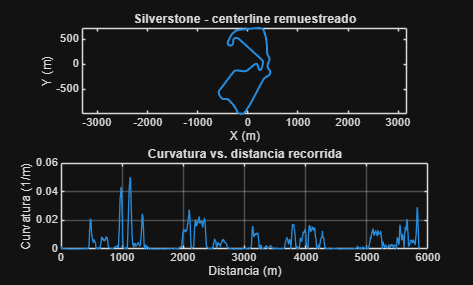

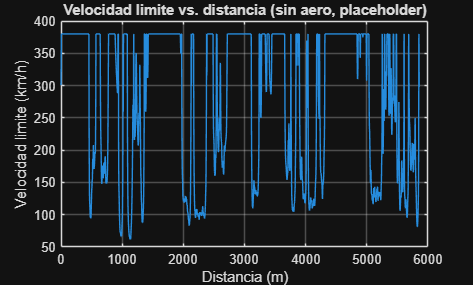

Guardado: silverstone_curvature.mat (trackX, trackY, trackS, curvature, v_max_kmh)


f1_track_curvature


if useRaceline
    fprintf('\n--- Cargando linea de carrera (reemplaza al centerline como referencia) ---\n');
    f1_load_raceline
end


--- Cargando linea de carrera (reemplaza al centerline como referencia) ---


Linea de carrera: 2894 puntos, 5788 m | curvatura p95 0.0157 1/m | salto de rumbo en la meta 0.35 grados



fprintf('\n--- Calculando perfil de velocidad de referencia (VelRef del piloto) ---\n');


--- Calculando perfil de velocidad de referencia (VelRef del piloto) ---


Vuelta ideal del perfil (alcanzable): 91.21 s
Perfil de velocidad: min 17.8 m/s (64 km/h) en s = 1114 m | max 90.0 m/s


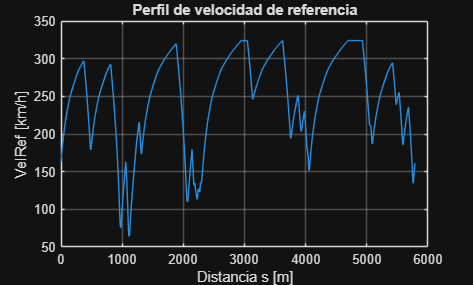

f1_speed_profile          % produce trackVref; debe ir DESPUES de la linea de carrera


fprintf('\n--- Cargando geometria de la linea de meta ---\n');


--- Cargando geometria de la linea de meta ---


f1_finish_line_params

psi_o (orientacion inicial): 0.907 rad (52.0 grados)
Meta en (-563.0, -515.7)
Direccion de avance: (0.616, 0.788)
